# Part 1: time domain FD solver to acoustic wave equation

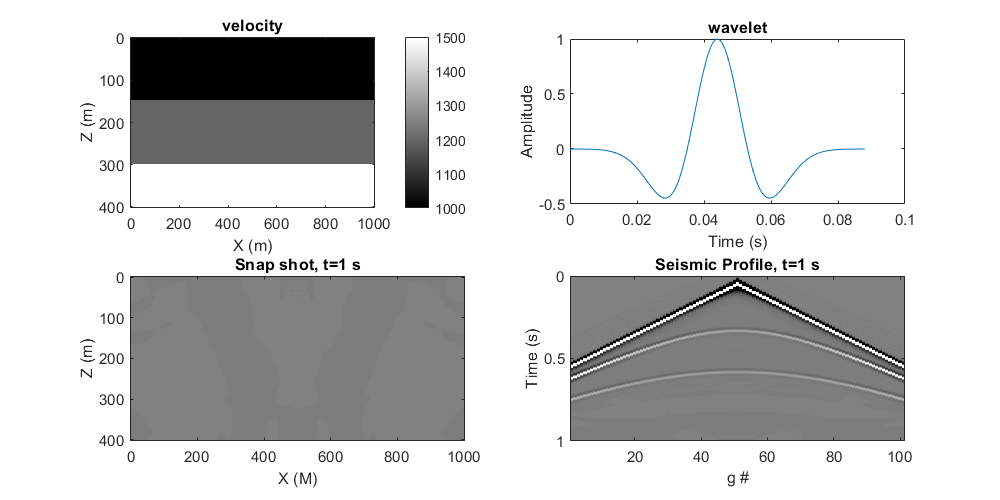


% define a 3 layer velocity model
vel=[repmat(1000,[1,30]), repmat(1200,[1,30]), repmat(1500,[1,21])];
vel=repmat(vel',[1 201]);
[nz,nx]=size(vel); dx=5; x = (0:nx-1)*dx; z = (0:nz-1)*dx;
% source and receiver geometry
sx = (nx-1)/2*dx; sz = 0;
gx=(0:2:(nx-1))*dx; gz=zeros(size(gx));
% FD params
nbc=40; nt=2001; dt=0.0005;isFS=false;
% source wavelet
freq=25; s=ricker(freq,dt);
% Plot the velocity and wavelet
figure(1);set(gcf,'position',[0 0 800 400]);subplot(221);imagesc(x,z,vel);colorbar;
xlabel('X (m)'); ylabel('Z (m)'); title('velocity');
figure(1);subplot(222);plot((0:numel(s)-1)*dt,s);
xlabel('Time (s)'); ylabel('Amplitude');title('wavelet');
% running FD
tic;
seis=a2d_mod_abc28_snapshot(vel,nbc,dx,nt,dt,s,sx,sz,gx,gz,isFS);

toc;

Elapsed time is 12.012247 seconds.


## Part 2: RTM

ng=numel(gx); g=1:ng; t=(0:nt-1)*dt;
% Smooth the true veolicyt to get the migration velocity model;
% vel_ss: smoothed velocity; refl_ss: reflectivity
[vel_ss,refl_ss]=vel_smooth(vel,3,3,1);
% Plot the velocity and seismic data;
figure(3);
set(gcf,'position',[0 0 1000 400]);
subplot(231);imagesc(x,z,vel);colorbar;
xlabel('X (m)'); ylabel('Z (m)'); title('velocity');
figure(3);
subplot(232);imagesc(g,t,seis);
colormap(gray);
title('Seismic Profile');ylabel('Time (s)');xlabel('g #');caxis([-0.25 0.25]);
% run RTM
tic;
[img,illum]=a2d_rtm_abc28_snapshot(seis,vel_ss,nbc,dx,nt,dt,s,sx,sz,gx,gz);
toc;

Elapsed time is 24.582672 seconds.


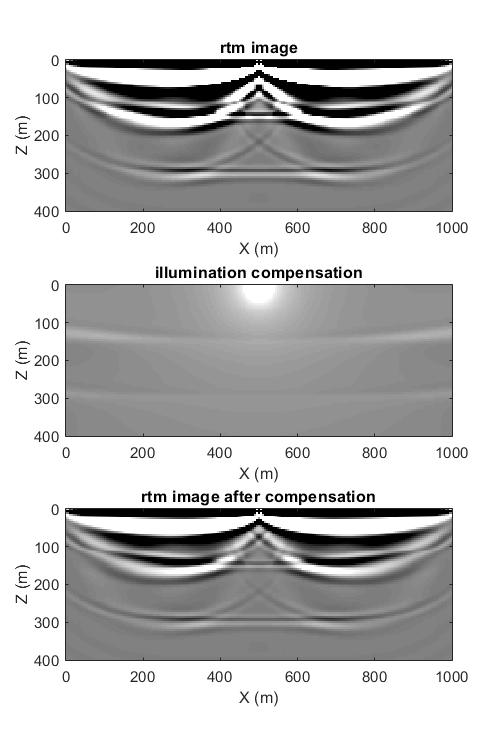

% Plot the illumination compensation, and see the impact.
figure(4); set(gcf,'position',[0 0 400 600]);colormap(gray);
subplot(311);imagesc(x,z,img);caxis([-10 10]);
xlabel('X (m)'); ylabel('Z (m)'); title('rtm image');
figure(4);subplot(312);imagesc(x,z,illum);caxis([-100 100]);
xlabel('X (m)'); ylabel('Z (m)'); title('illumination compensation');
figure(4);subplot(313);imagesc(x,z,img./illum);caxis([-1 1]);
xlabel('X (m)'); ylabel('Z (m)'); title('rtm image after compensation');

% Mute the direct wave, and rerun the migration.
vel_homo=zeros(size(vel))+min(vel(:));
tic;
seis_homo=a2d_mod_abc28(vel_homo,nbc,dx,nt,dt,s,sx,sz,gx,gz,isFS);
toc;

Elapsed time is 3.516864 seconds.


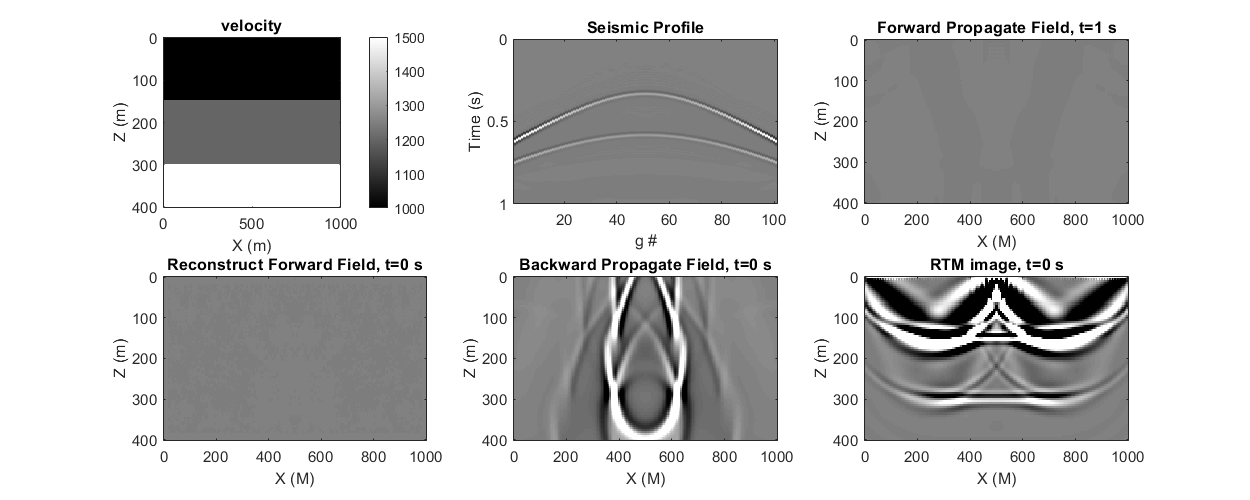

figure(3);
set(gcf,'position',[0 0 1000 400]);subplot(231);imagesc(x,z,vel);colorbar;
xlabel('X (m)'); ylabel('Z (m)'); title('velocity');
seis=seis-seis_homo;
figure(3); subplot(232);imagesc(g,t,seis);figure_title='Seismic Profile';
title(figure_title);ylabel('Time (s)');xlabel('g #');caxis([-0.25 0.25]);
[img,illum]=a2d_rtm_abc28_snapshot(seis,vel_ss,nbc,dx,nt,dt,s,sx,sz,gx,gz);

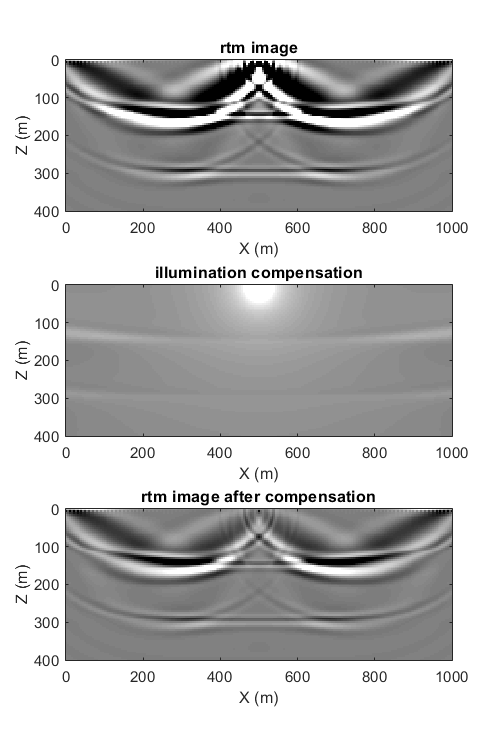

figure(5); set(gcf,'position',[0 0 400 600]);colormap(gray);
subplot(311);imagesc(x,z,img);caxis([-10 10]);xlabel('X (m)'); ylabel('Z (m)'); title('rtm image');
figure(5);subplot(312);imagesc(x,z,illum);caxis([-100 100]);xlabel('X (m)'); ylabel('Z (m)'); title('illumination compensation');
figure(5);subplot(313);imagesc(x,z,img./illum);caxis([-1 1]);xlabel('X (m)'); ylabel('Z (m)'); title('rtm image after compensation');

% RTM with all shots
% Initial the parallel mode;
ncpu = 4;
myCluster = parcluster('local');
myCluster.NumWorkers = ncpu;
parpool(ncpu);

Starting parallel pool (parpool) using the 'local' profile ...
connected to 4 workers.


% Define the source and receiver geometry;
gx=(0:2:(nx-1))*dx; ng=numel(gx);
sx=(0:4:(nx-1))*dx; ns=numel(sx); sz=zeros(ns);
% Generate the syhthetic seismic data and mute the direct wave;
tic;seis=zeros(nt,ng,ns);
disp('Modeling to generate data');

Modeling to generate data


parfor is=1:ns
    display(['Modeling, is=',num2str(is),', ns=',num2str(ns)]);
    seis(:,:,is)=a2d_mod_abc28(vel,nbc,dx,nt,dt,s,sx(is),sz(is),gx,gz,isFS);
    seis_homo=a2d_mod_abc28(vel_homo,nbc,dx,nt,dt,s,sx(is),sz(is),gx,gz,isFS);
    seis(:,:,is)=seis(:,:,is)-seis_homo;
end

Modeling, is=1, ns=51
Modeling, is=2, ns=51
Modeling, is=4, ns=51
Modeling, is=8, ns=51
Modeling, is=3, ns=51
Modeling, is=7, ns=51
Modeling, is=22, ns=51
Modeling, is=15, ns=51
Modeling, is=6, ns=51
Modeling, is=14, ns=51
Modeling, is=21, ns=51
Modeling, is=29, ns=51
Modeling, is=20, ns=51
Modeling, is=28, ns=51
Modeling, is=5, ns=51
Modeling, is=13, ns=51
Modeling, is=12, ns=51
Modeling, is=19, ns=51
Modeling, is=27, ns=51
Modeling, is=35, ns=51
Modeling, is=11, ns=51
Modeling, is=18, ns=51
Modeling, is=34, ns=51
Modeling, is=26, ns=51
Modeling, is=33, ns=51
Modeling, is=10, ns=51
Modeling, is=17, ns=51
Modeling, is=25, ns=51
Modeling, is=32, ns=51
Modeling, is=9, ns=51
Modeling, is=16, ns=51
Modeling, is=24, ns=51
Modeling, is=31, ns=51
Modeling, is=42, ns=51
Modeling, is=23, ns=51
Modeling, is=39, ns=51
Modeling, is=30, ns=51
Modeling, is=41, ns=51
Modeling, is=38, ns=51
Modeling, is=45, ns=51
Modeling, is=47, ns=51
Modeling, is=40, ns=51
Modeling, is=37, ns=51
Modeling, is=44, ns=

% Forward propagate to save boundaries;
bc_top=zeros(5,nx,nt,ns); bc_bottom=zeros(5,nx,nt,ns);
bc_left=zeros(nz,5,nt,ns);bc_right=zeros(nz,5,nt,ns);
bc_p_nt=zeros(nz+2*nbc,nx+2*nbc,ns);bc_p_nt_1=zeros(nz+2*nbc,nx+2*nbc,ns);
disp('Modeling to save BC');

Modeling to save BC


parfor is=1:ns
    display(['Modeling, is=',num2str(is),', ns=',num2str(ns)]);
    [~,bc_top(:,:,:,is),bc_bottom(:,:,:,is),bc_left(:,:,:,is),...
        bc_right(:,:,:,is),bc_p_nt(:,:,is),bc_p_nt_1(:,:,is)]...
        =a2d_mod_abc28(vel_ss,nbc,dx,nt,dt,s,sx(is),sz(is),gx,gz,isFS);
end

Modeling, is=1, ns=51
Modeling, is=2, ns=51
Modeling, is=4, ns=51
Modeling, is=8, ns=51
Modeling, is=3, ns=51
Modeling, is=7, ns=51
Modeling, is=15, ns=51
Modeling, is=22, ns=51
Modeling, is=14, ns=51
Modeling, is=6, ns=51
Modeling, is=21, ns=51
Modeling, is=29, ns=51
Modeling, is=13, ns=51
Modeling, is=20, ns=51
Modeling, is=5, ns=51
Modeling, is=28, ns=51
Modeling, is=12, ns=51
Modeling, is=19, ns=51
Modeling, is=27, ns=51
Modeling, is=35, ns=51
Modeling, is=11, ns=51
Modeling, is=26, ns=51
Modeling, is=34, ns=51
Modeling, is=18, ns=51
Modeling, is=10, ns=51
Modeling, is=33, ns=51
Modeling, is=17, ns=51
Modeling, is=25, ns=51
Modeling, is=9, ns=51
Modeling, is=32, ns=51
Modeling, is=16, ns=51
Modeling, is=24, ns=51
Modeling, is=31, ns=51
Modeling, is=23, ns=51
Modeling, is=39, ns=51
Modeling, is=42, ns=51
Modeling, is=30, ns=51
Modeling, is=38, ns=51
Modeling, is=41, ns=51
Modeling, is=45, ns=51
Modeling, is=37, ns=51
Modeling, is=40, ns=51
Modeling, is=44, ns=51
Modeling, is=47, ns=

% RTM
img=zeros(nz,nx,ns);illum=zeros(nz,nx,ns);
parfor is=1:ns
    display(['RTM, is=',num2str(is),' ns=',num2str(ns)]);
    [img(:,:,is),illum(:,:,is)]=a2d_rtm_abc28(seis(:,:,is),vel_ss,nbc,dx,nt,dt,s,sx(is),sz(is),gx,gz,...
        bc_top(:,:,:,is),bc_bottom(:,:,:,is),bc_left(:,:,:,is),...
        bc_right(:,:,:,is),bc_p_nt(:,:,is),bc_p_nt_1(:,:,is));
end

RTM, is=1 ns=51
RTM, is=2 ns=51
RTM, is=4 ns=51
RTM, is=8 ns=51
RTM, is=15 ns=51
RTM, is=22 ns=51
RTM, is=3 ns=51
RTM, is=7 ns=51
RTM, is=21 ns=51
RTM, is=14 ns=51
RTM, is=29 ns=51
RTM, is=6 ns=51
RTM, is=20 ns=51
RTM, is=13 ns=51
RTM, is=28 ns=51
RTM, is=5 ns=51
RTM, is=19 ns=51
RTM, is=12 ns=51
RTM, is=27 ns=51
RTM, is=35 ns=51
RTM, is=11 ns=51
RTM, is=18 ns=51
RTM, is=26 ns=51
RTM, is=34 ns=51
RTM, is=10 ns=51
RTM, is=17 ns=51
RTM, is=25 ns=51
RTM, is=33 ns=51
RTM, is=9 ns=51
RTM, is=16 ns=51
RTM, is=24 ns=51
RTM, is=32 ns=51
RTM, is=39 ns=51
RTM, is=42 ns=51
RTM, is=23 ns=51
RTM, is=31 ns=51
RTM, is=41 ns=51
RTM, is=38 ns=51
RTM, is=30 ns=51
RTM, is=45 ns=51
RTM, is=37 ns=51
RTM, is=40 ns=51
RTM, is=47 ns=51
RTM, is=44 ns=51
RTM, is=36 ns=51
RTM, is=48 ns=51
RTM, is=46 ns=51
RTM, is=43 ns=51
RTM, is=49 ns=51
RTM, is=51 ns=51
RTM, is=50 ns=51


toc;

Elapsed time is 633.500314 seconds.


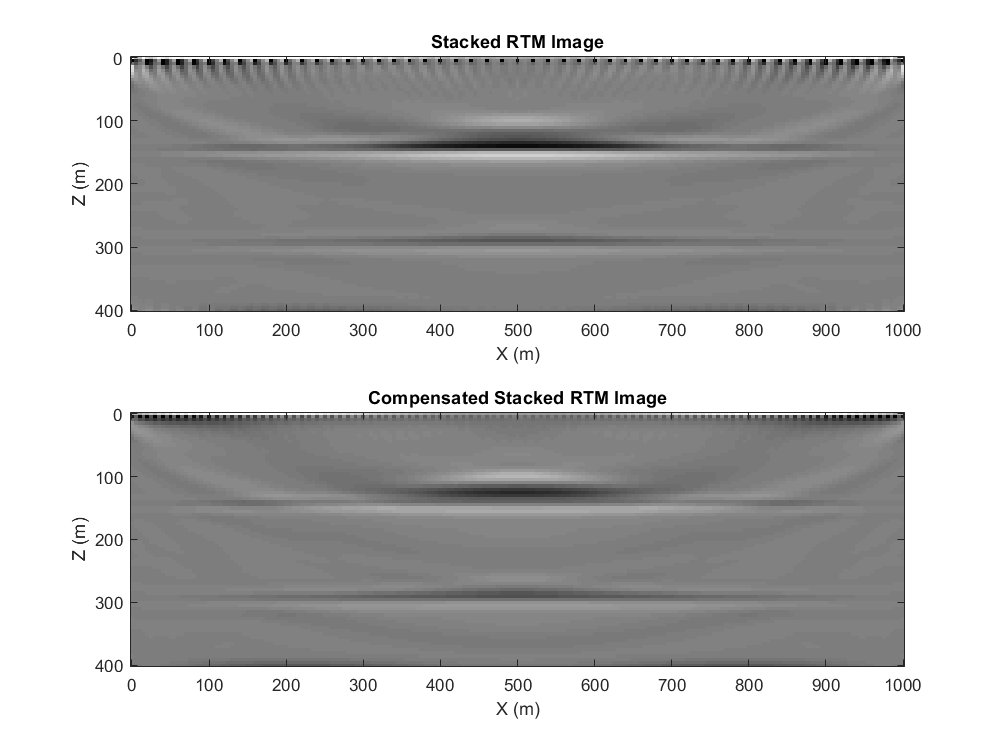

% Stack the prestack image, apply the highpass filter and plot the final results
image=sum(img,3);image_illum=sum(img./illum,3);
figure(6);set(gcf,'position',[0 0 800 600]);colormap(gray);
subplot(211);
imagesc(x,z,highpass(image,10,2));caxis([-1000 1000]);
xlabel('X (m)'); ylabel('Z (m)'); title('Stacked RTM Image');
figure(6);subplot(212);imagesc(x,z,highpass(image_illum,10,2));caxis([-50 50]);
xlabel('X (m)'); ylabel('Z (m)'); title('Compensated Stacked RTM Image');

% Exit the parallel mode;
delete(gcp);

## Part 3: Born modeling and adjoint test lab

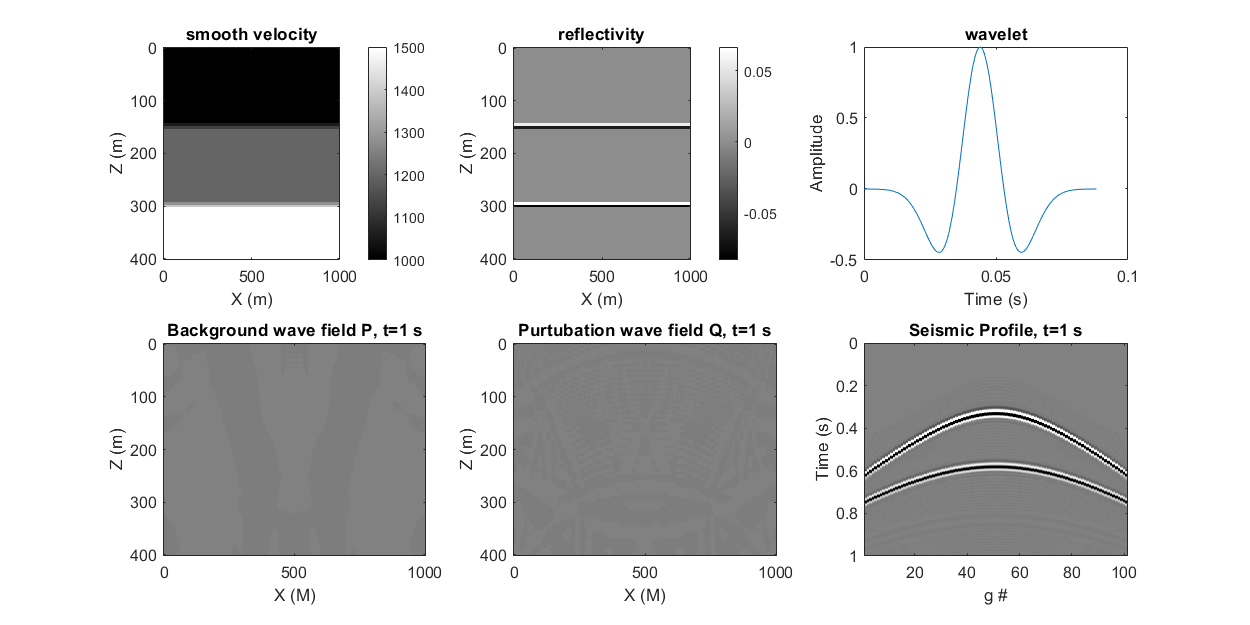

% Plot the background velocity, reflectivity model and wavelet;
figure(2);
set(gcf,'position',[0 0 1000 500]);colormap(gray);
subplot(231);imagesc(x,z,vel_ss);colorbar;
xlabel('X (m)'); ylabel('Z (m)'); title('smooth velocity');
figure(2);subplot(232);imagesc(x,z,refl_ss);colorbar;
xlabel('X (m)'); ylabel('Z (m)'); title('reflectivity');
figure(2);subplot(233);plot((0:numel(s)-1)*dt,s);
xlabel('Time (s)'); ylabel('Amplitude');title('wavelet');
% Run the modeling code,
% watch the movie of wave propagation including both background wave field and pertubation wave field,
% then plot the seismic data;
tic;
seis=a2d_bmod_abc28_snapshot(vel_ss,refl_ss,nbc,dx,nt,dt,s,sx,sz,gx,gz,isFS);

toc;

Elapsed time is 15.293807 seconds.


% Do the RTM with the generated born data;
% Forward Modeling to save BC
tic; [~,bc_top,bc_bottom,bc_left,bc_right,bc_p_nt,bc_p_nt_1]=...
    a2d_mod_abc28(vel_ss,nbc,dx,nt,dt,s,sx,sz,gx,gz,isFS);toc;

Elapsed time is 7.458314 seconds.


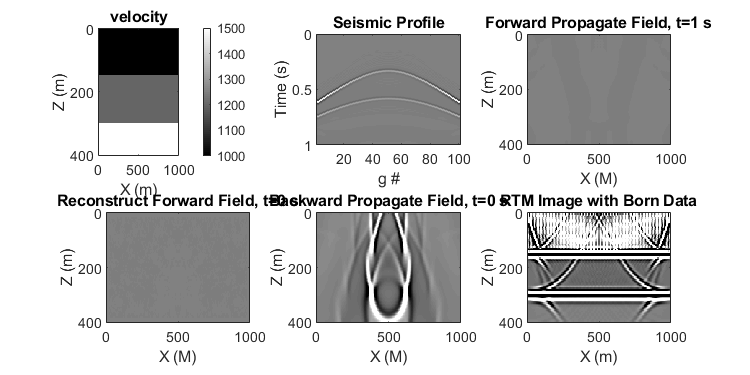

% RTM
img=a2d_rtm_abc28(seis,vel_ss,nbc,dx,nt,dt,s,sx,sz,gx,gz,...
    bc_top,bc_bottom,bc_left,bc_right,bc_p_nt,bc_p_nt_1);
figure(3);
set(gcf,'position',[0 0 600 300]);colormap(gray);
imagesc(x,z,img);caxis([-100 100]);
xlabel('X (m)'); ylabel('Z (m)'); title('RTM Image with Born Data');

% Adjoint test, 
% since we have m, Lm and LTLm now, we will calculate LLTLm to examine our operator 
% to see if they can pass the adjoint test.
tic;seis_new=a2d_bmod_abc28(vel_ss,img,nbc,dx,nt,dt,s,sx,sz,gx,gz,isFS);toc;

Elapsed time is 12.844023 seconds.


a=sum(refl_ss(:).*img(:));
b=sum(seis(:).^2);
c=sum(img(:).^2);
d=sum(seis(:).*seis_new(:));
display(['<Lm,Lm> = ',num2str(b)]);

<Lm,Lm> = 35581.547


display(['<m,LTLm> = ',num2str(a)]);

<m,LTLm> = 35461.061


display(['<LTLm,LTLm> = ',num2str(c)]);

<LTLm,LTLm> = 1330450760.4395


display(['<Lm,LLTLm> = ',num2str(d)]);

<Lm,LLTLm> = 1326882986.5109
